#### Load the dataset ,resize it, divide it into training and validation set

FlowerData =imageDatastore("FLR_IMGS","IncludeSubfolders",true,"LabelSource","foldernames");

% size= 227;   % resize dimension for alexnet training 227 x 277 x 3
% for i=1:length(FlowerData.Files)
%     
%     a =imread(char(FlowerData.Files(i)));
%     a=imresize(a,[size,size]);
%     imwrite(a,char(FlowerData.Files(i)));
% end

[imdsTrain, imdsValidation] = splitEachLabel(FlowerData,0.8); % 
% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([227 227 3],imdsTrain);
augimdsValidation = augmentedImageDatastore([227 227 3],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.001,...
    "MiniBatchSize",20,...
    "MaxEpochs",20,...
    "Shuffle","every-epoch",...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Transfer Learning Layer model FlowerNet using Alexnet

FlowerNet = alexnet; % this will copy the layer architecture of alexnet into 
                     % FlowerNet Varibale
                     
layers = FlowerNet.Layers;
layers(end-2)=fullyConnectedLayer(30,'Name','Fully Connected '); % 30 types of flower
layers(end)=classificationLayer;
layers

layers =   25x1 Layer array with layers:

     1   'data'               Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'              Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'              ReLU                          ReLU
     4   'norm1'              Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'              Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'              Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'              ReLU                          ReLU
     8   'norm2'              Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'      

## Train Network

Train the network using the specified options and training data.

Training on single GPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:02 |        5.00% |        5.67% |       7.7968 |       4.3407 |          0.0010 |


|       1 |          50 |       00:00:12 |       45.00% |       57.83% |       2.0008 |       1.5510 |          0.0010 |


|       1 |         100 |       00:00:21 |       85.00% |       78.17% |       0.8258 |       0.7365 |          0.0010 |


|       2 |         150 |       00:00:31 |       85.00% |       92.00% |       0.6224 |       0.3251 |          0.0010 |


|       2 |         200 |       00:00:41 |       80.00% |       87.17% |       0.5149 |       0.3850 |          0.0010 |


|       3 |         250 |       00:00:51 |       90.00% |       93.67% |       0.4237 |       0.1984 |          0.0010 |


|       3 |         300 |       00:01:01 |      100.00% |       96.50% |       0.0884 |       0.1139 |          0.0010 |


|       3 |         350 |       00:01:11 |      100.00% |       97.17% |       0.0468 |       0.0960 |          0.0010 |


|       4 |         400 |       00:01:21 |       90.00% |       96.33% |       0.1126 |       0.0852 |          0.0010 |


|       4 |         450 |       00:01:31 |       95.00% |       99.50% |       0.0847 |       0.0269 |          0.0010 |


|       5 |         500 |       00:01:41 |      100.00% |       96.67% |       0.0531 |       0.0953 |          0.0010 |


|       5 |         550 |       00:01:51 |       95.00% |       97.17% |       0.1916 |       0.1187 |          0.0010 |


|       5 |         600 |       00:02:01 |      100.00% |       99.17% |       0.0028 |       0.0480 |          0.0010 |


|       6 |         650 |       00:02:11 |       95.00% |       99.17% |       0.1531 |       0.0219 |          0.0010 |


|       6 |         700 |       00:02:21 |      100.00% |       99.33% |       0.0048 |       0.0202 |          0.0010 |


|       7 |         750 |       00:02:31 |      100.00% |       99.00% |       0.0224 |       0.0239 |          0.0010 |


|       7 |         800 |       00:02:40 |      100.00% |       99.00% |       0.0162 |       0.0321 |          0.0010 |


|       8 |         850 |       00:02:50 |      100.00% |       99.17% |       0.0216 |       0.0267 |          0.0010 |


|       8 |         900 |       00:03:00 |      100.00% |       98.83% |       0.0160 |       0.0395 |          0.0010 |


|       8 |         950 |       00:03:11 |      100.00% |       98.67% |       0.0029 |       0.0405 |          0.0010 |


|       9 |        1000 |       00:03:21 |      100.00% |      100.00% |   4.2282e-05 |       0.0026 |          0.0010 |


|       9 |        1050 |       00:03:31 |      100.00% |       99.83% |       0.0001 |       0.0074 |          0.0010 |


|      10 |        1100 |       00:03:41 |      100.00% |       99.67% |       0.0009 |       0.0133 |          0.0010 |


|      10 |        1150 |       00:03:51 |      100.00% |       99.83% |       0.0005 |       0.0053 |          0.0010 |


|      10 |        1200 |       00:04:01 |       95.00% |       97.83% |       0.0730 |       0.0990 |          0.0010 |


|      11 |        1250 |       00:04:11 |      100.00% |       99.00% |       0.0011 |       0.0389 |          0.0010 |


|      11 |        1300 |       00:04:21 |      100.00% |       99.50% |       0.0083 |       0.0262 |          0.0010 |


|      12 |        1350 |       00:04:31 |      100.00% |       99.67% |       0.0004 |       0.0175 |          0.0010 |


|      12 |        1400 |       00:04:41 |      100.00% |       99.67% |       0.0029 |       0.0248 |          0.0010 |


|      13 |        1450 |       00:04:51 |      100.00% |       98.67% |       0.0001 |       0.0463 |          0.0010 |


|      13 |        1500 |       00:05:01 |      100.00% |       99.83% |       0.0047 |       0.0070 |          0.0010 |


|      13 |        1550 |       00:05:11 |      100.00% |       99.33% |       0.0001 |       0.0274 |          0.0010 |


|      14 |        1600 |       00:05:23 |      100.00% |       99.67% |       0.0007 |       0.0145 |          0.0010 |


|      14 |        1650 |       00:05:33 |      100.00% |       99.50% |   9.2627e-05 |       0.0137 |          0.0010 |


|      15 |        1700 |       00:05:43 |      100.00% |       99.67% |       0.0002 |       0.0157 |          0.0010 |


|      15 |        1750 |       00:05:54 |      100.00% |       99.67% |       0.0002 |       0.0119 |          0.0010 |


|      15 |        1800 |       00:06:04 |      100.00% |       99.17% |       0.0075 |       0.0141 |          0.0010 |


|      16 |        1850 |       00:06:14 |      100.00% |       99.50% |       0.0005 |       0.0197 |          0.0010 |


|      16 |        1900 |       00:06:24 |      100.00% |       99.50% |   1.9082e-05 |       0.0170 |          0.0010 |


|      17 |        1950 |       00:06:34 |      100.00% |       99.50% |       0.0002 |       0.0182 |          0.0010 |


|      17 |        2000 |       00:06:44 |      100.00% |       99.50% |       0.0030 |       0.0154 |          0.0010 |


|      18 |        2050 |       00:06:53 |      100.00% |       99.67% |   3.8897e-05 |       0.0138 |          0.0010 |


|      18 |        2100 |       00:07:04 |      100.00% |       99.67% |       0.0001 |       0.0103 |          0.0010 |


|      18 |        2150 |       00:07:14 |      100.00% |       99.83% |   4.6612e-06 |       0.0075 |          0.0010 |


|      19 |        2200 |       00:07:24 |      100.00% |       99.83% |   2.5499e-05 |       0.0064 |          0.0010 |


|      19 |        2250 |       00:07:34 |      100.00% |       99.83% |   6.7519e-05 |       0.0073 |          0.0010 |


|      20 |        2300 |       00:07:44 |      100.00% |       99.17% |   8.0120e-05 |       0.0296 |          0.0010 |


|      20 |        2350 |       00:07:54 |      100.00% |       99.83% |       0.0003 |       0.0078 |          0.0010 |


|      20 |        2400 |       00:08:04 |       95.00% |       99.83% |       0.1026 |       0.0058 |          0.0010 |


|======================================================================================================================|


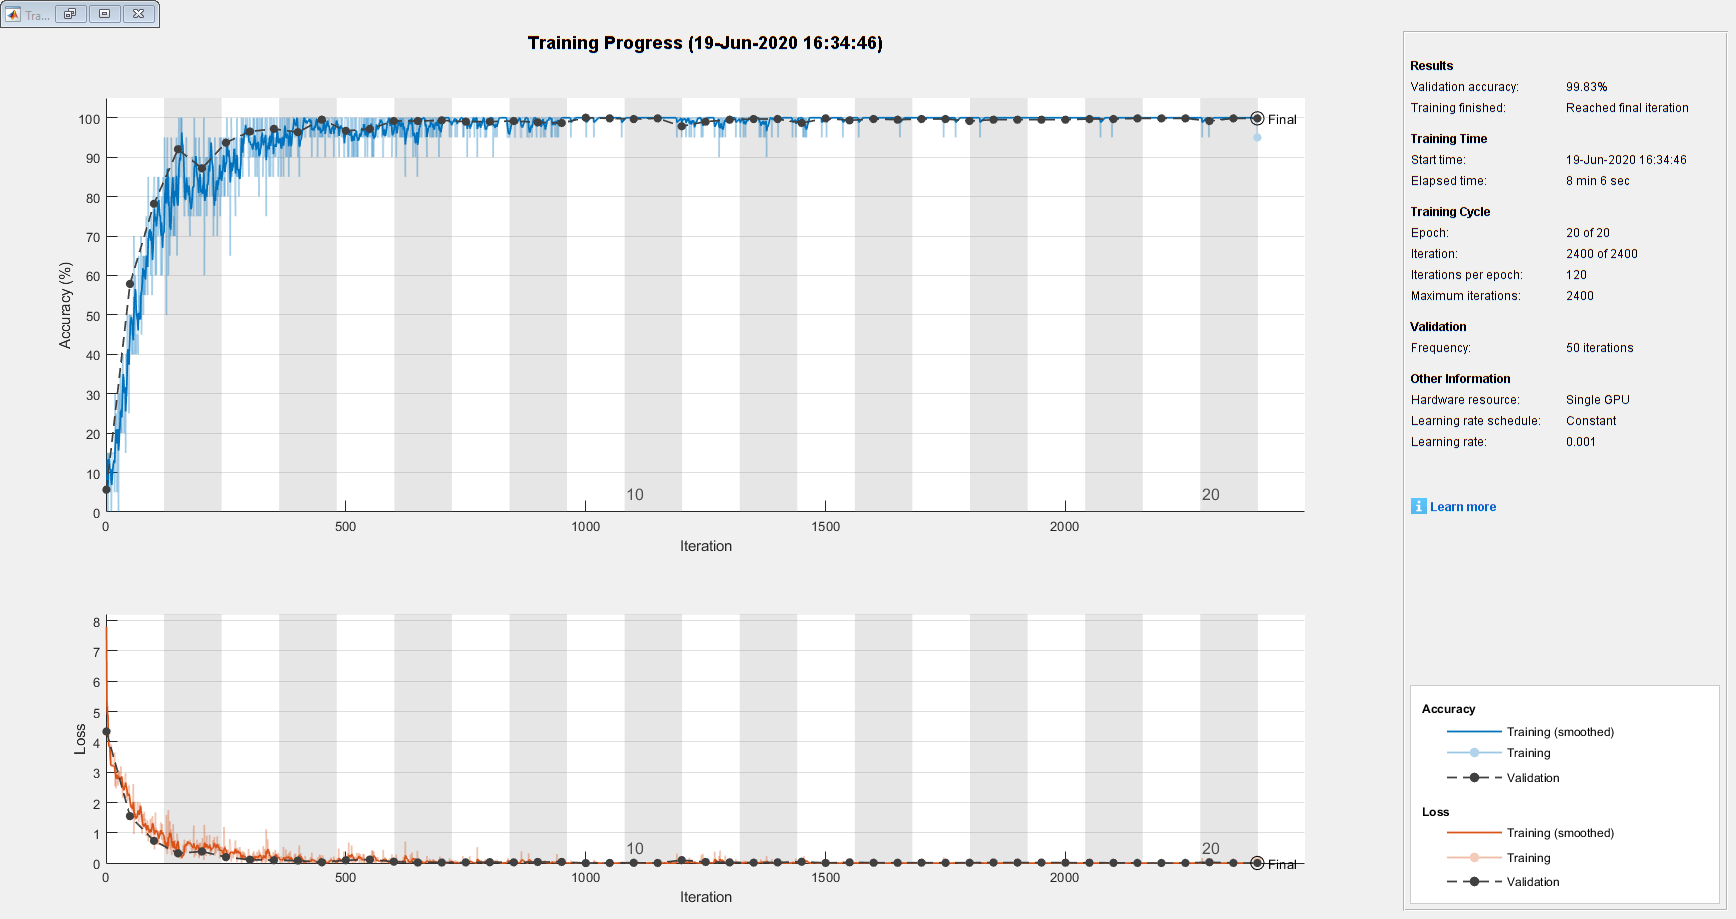

[FlowerNet, traininfo] = trainNetwork(augimdsTrain,layers,opts);

save FlowerNet
